load("estimated_parameters.mat")
Vpp = 20;

A1_min = deg2rad(-17);
A1_max = deg2rad(31);
delta_A1 = A1_max - A1_min;


A2_min = deg2rad(-27);
A2_max = deg2rad(27);
delta_A2 = A2_max - A2_min;


Gt0=tf(dc_gain0,[ 0.8*tau0 1 0])


Gt0 =
 
      -1.58
  --------------
  0.0404 s^2 + s
 
Continuous-time transfer function.



Gt1=tf(dc_gain1,[ 0.8*tau1 1 0]);

Gt0_min = delta_A1/Vpp;
Gt0_min_db = mag2db(Gt0_min);

Gt1_min = delta_A2/Vpp;
Gt1_min_db = mag2db(Gt1_min);

lowest_Gain = min(Gt0_min,Gt1_min);

mag2db(lowest_Gain)

ans = -27.5582


Gt_limit = tf(lowest_Gain);

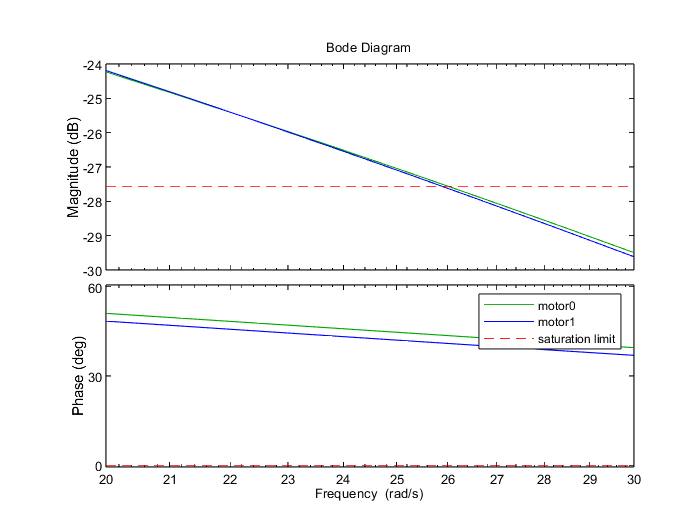

opts = bodeoptions;
opts.MagUnits = "dB";
% opts.FreqScale = "linear";
% opts.PhaseVisible = "off";
figure
bodeplot(Gt0,"g",Gt1,"b",Gt_limit, '--r',{20,30},opts)
legend(["motor0","motor1","saturation limit"])

We can see how the bode plot goes below the saturation limit at 26rad/s. This is a candidate for a bandwidth of the feedback loop.

opts = pidtuneOptions('PhaseMargin',70,'DesignFocus','reference-tracking');
Gt0d = c2d(Gt1,1/500);
[C_pd0,info] = pidtune(Gt0d,'PD',26.0,opts)


C_pd0 =
 
              z-1 
  Kp + Kd * ------
              Ts  

  with Kp = -21, Kd = -0.47, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PD controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 26
           PhaseMargin: 70


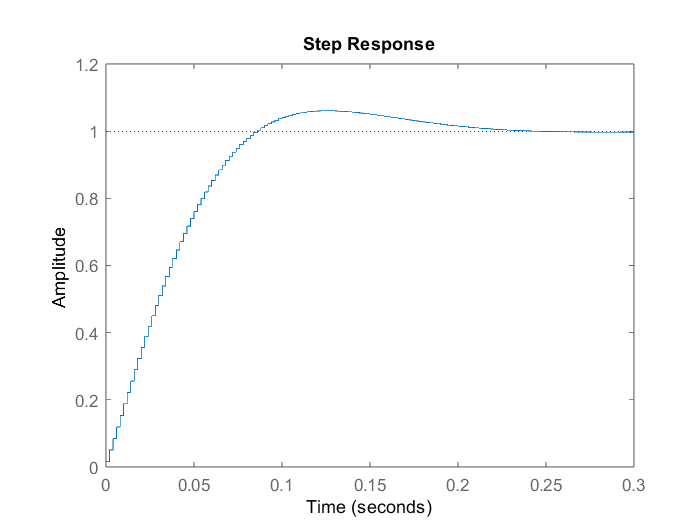


T_pd = feedback(C_pd0*Gt0d,1);
step(T_pd);

stepinfo(T_pd)

ans = struct with fields:
        RiseTime: 0.0620
    SettlingTime: 0.1920
     SettlingMin: 0.9126
     SettlingMax: 1.0607
       Overshoot: 6.0723
      Undershoot: 0
            Peak: 1.0607
        PeakTime: 0.1240


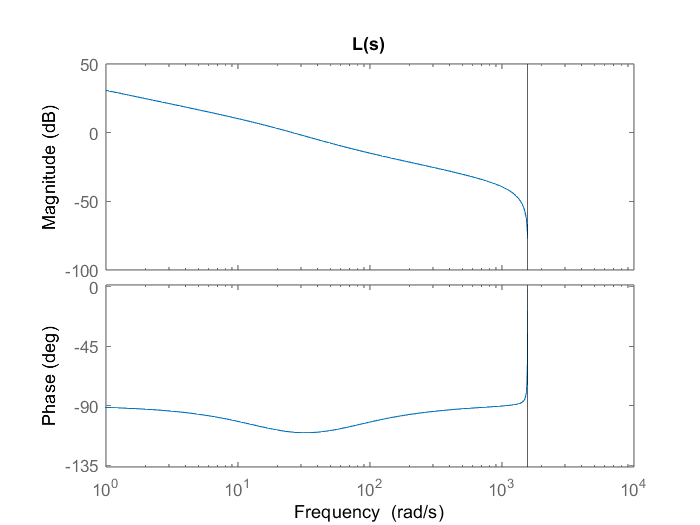

Ld=C_pd0*Gt0d;
bode(Ld)
title("L(s)")

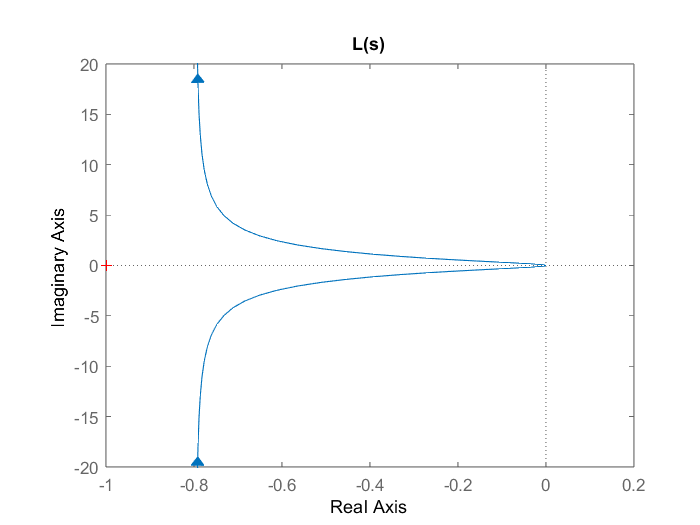

nyqplot(Ld)
title("L(s)")

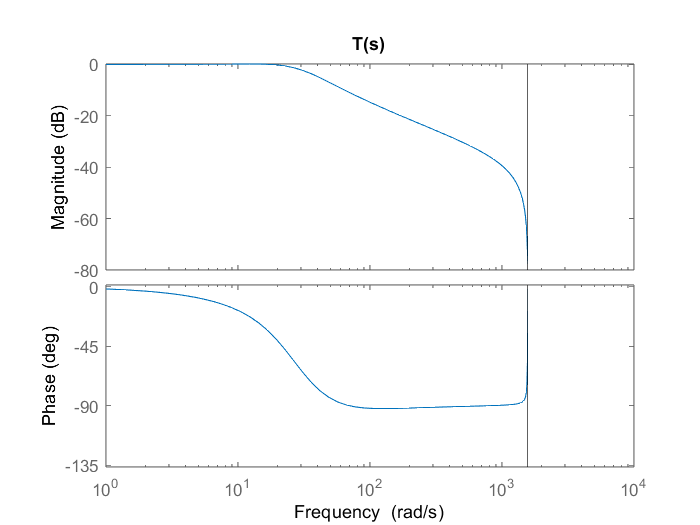



bode(T_pd)
title("T(s)")

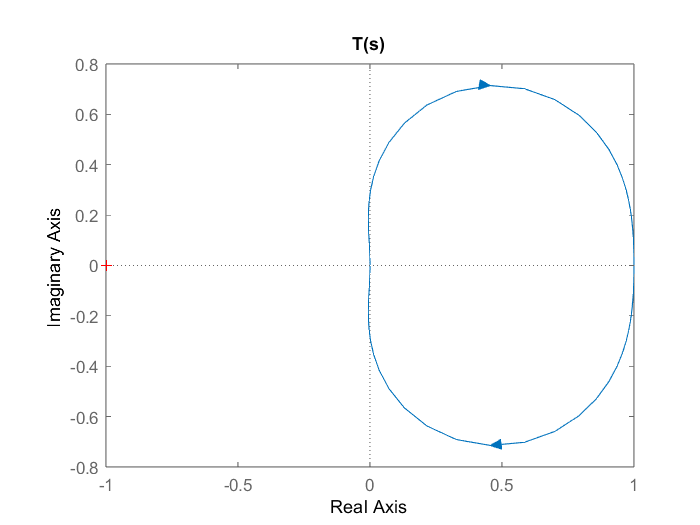

nyqplot(T_pd)
title("T(s)")

opts = pidtuneOptions('PhaseMargin',90,'DesignFocus','reference-tracking');

Gt0_star = Gt0 * tf([1],[1 0])


Gt0_star =
 
       -1.58
  ----------------
  0.0404 s^3 + s^2
 
Continuous-time transfer function.



Gt0d_star = c2d(Gt0_star,1/500);
[C_pd0_star,info] = pidtune(Gt0d,'PD',26.0,opts)


C_pd0_star =
 
              z-1 
  Kp + Kd * ------
              Ts  

  with Kp = -15.8, Kd = -0.714, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PD controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 26
           PhaseMargin: 90.0000



T_pd_star = feedback(C_pd0_star*Gt0d_star,-1);
step(T_pd);

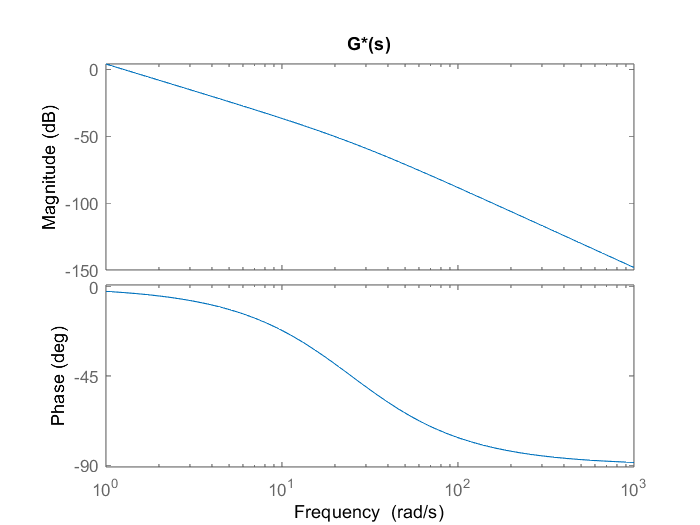

Ld_star=C_pd0_star*Gt0d_star;
bode(Gt0_star);
title("G*(s)")

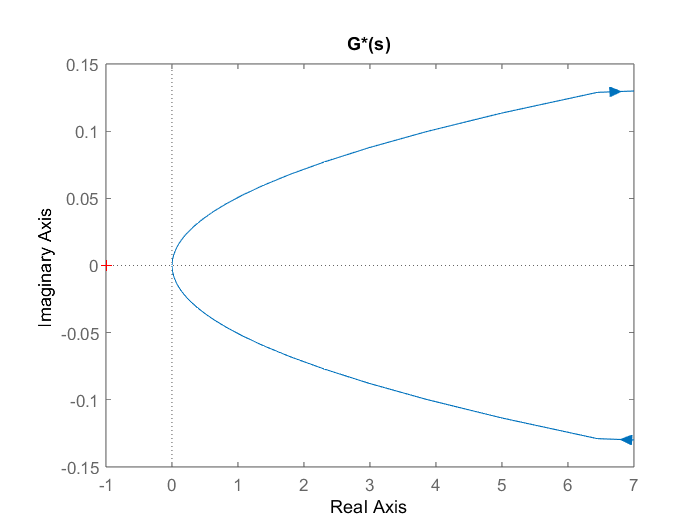

nyqplot(Gt0_star)
title("G*(s)")

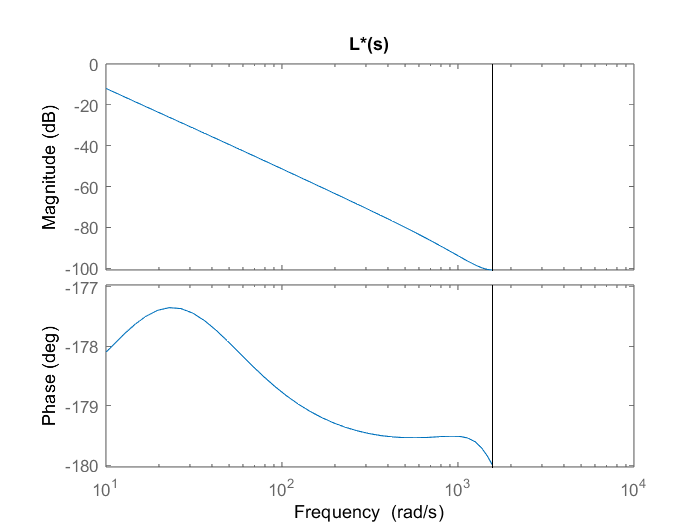


bode(Ld_star)
title("L*(s)")

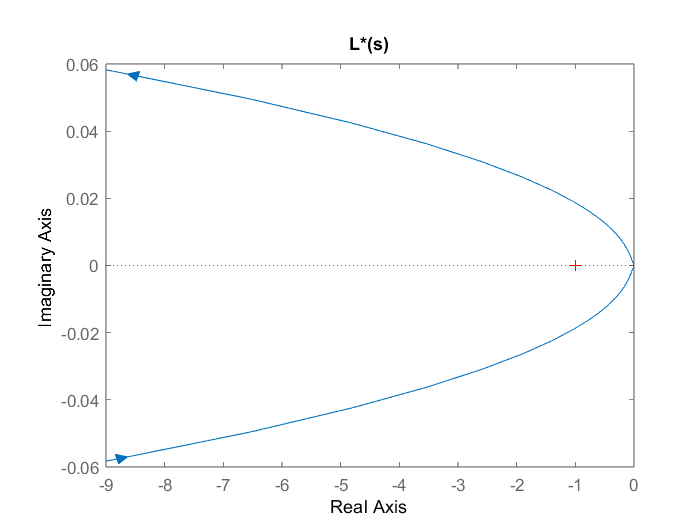

nyqplot(Ld_star)
title("L*(s)")

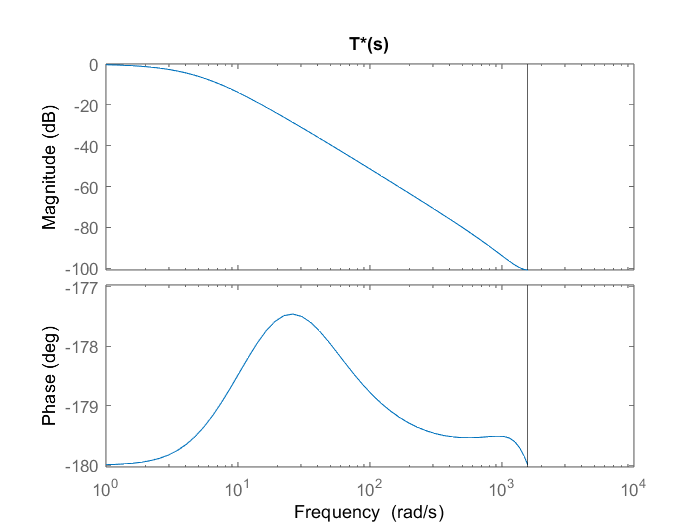



bode(T_pd_star)
title("T*(s)")

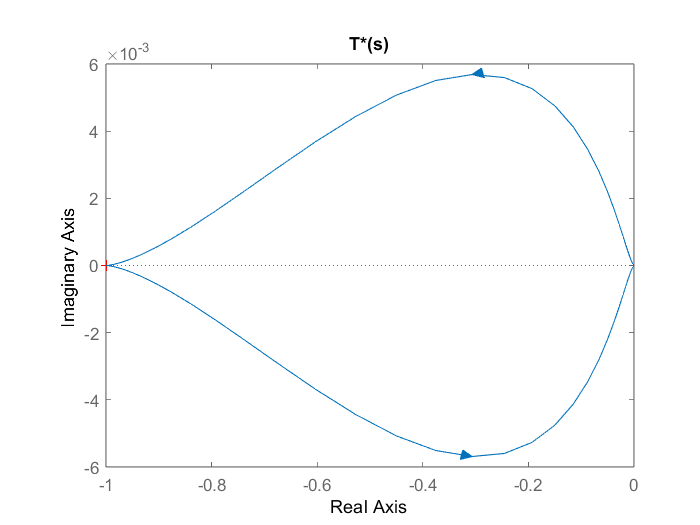

nyqplot(T_pd_star)
title("T*(s)")

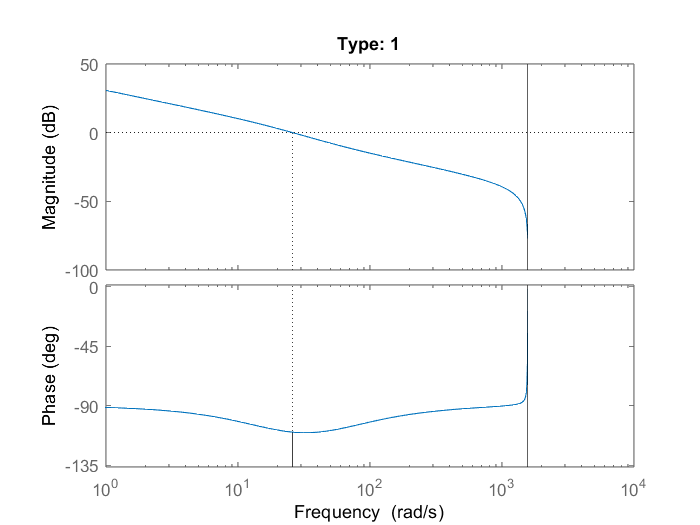

margin(Ld);
title("Type: 1")

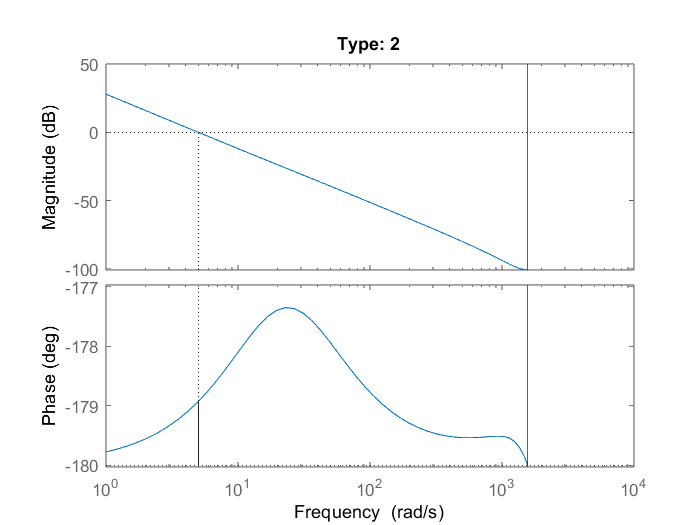


margin(Ld_star);
title("Type: 2")

% Loop Shaping

Gt0_star = Gt0 * tf([1],[1 0]) 


Gt0_star =
 
       -1.58
  ----------------
  0.0404 s^3 + s^2
 
Continuous-time transfer function.




Kc = abs(evalfr(Gt0_star,j*20)) / abs(evalfr(Gt0_star,j*26))

Kc = 1.9064


R = -Kc * tf([25 -10 1],[0.02 1 0])


R =
 
  -47.66 s^2 + 19.06 s - 1.906
  ----------------------------
          0.02 s^2 + s
 
Continuous-time transfer function.



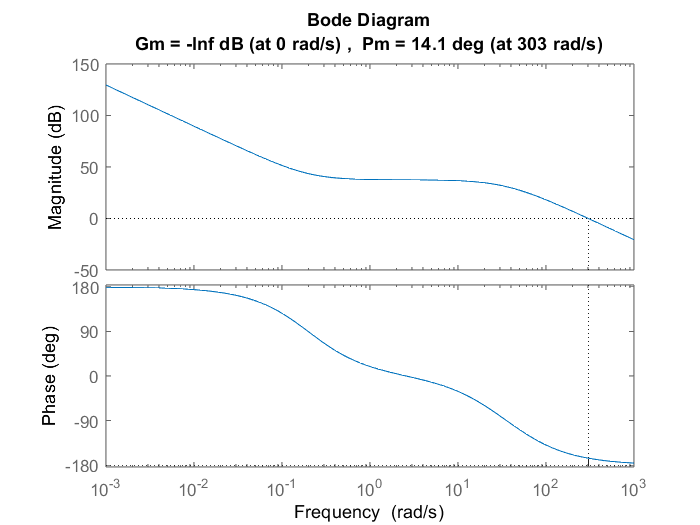


L_ls= R * Gt0;
margin(L_ls)

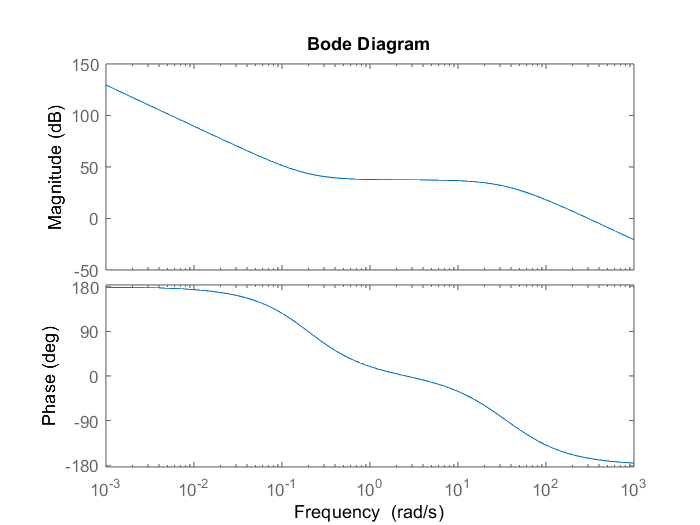

bode(L_ls)

T_ls = feedback(L_ls,+1)


T_ls =
 
                75.3 s^2 - 30.12 s + 3.012
  ------------------------------------------------------
  0.000808 s^4 + 0.0604 s^3 + 76.3 s^2 - 30.12 s + 3.012
 
Continuous-time transfer function.



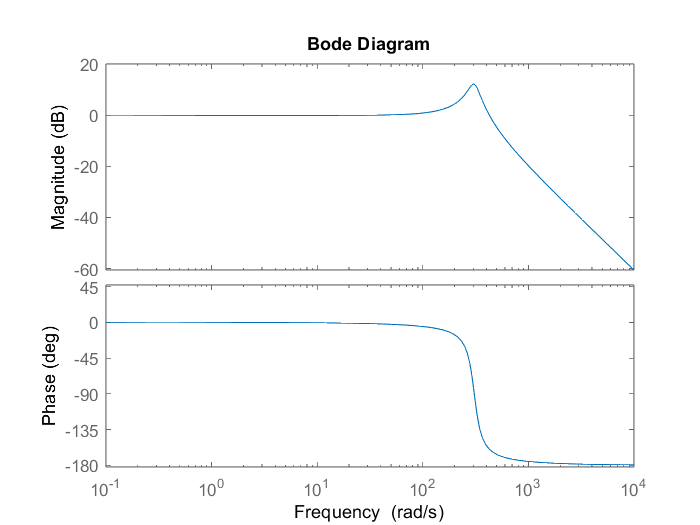

bode(T_ls)

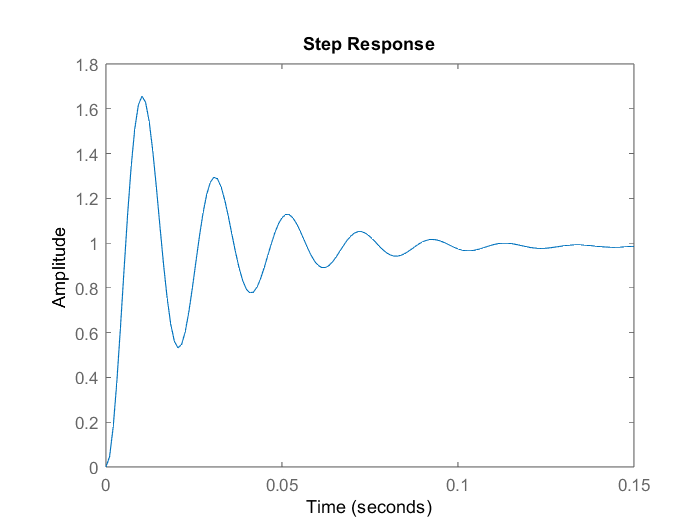


step(T_ls)